## Initialize

clearvars -except mapCD
addpath D:\gitTmp
addpath D:\od\OneDrive\matlab\myFunction\myftn\
addpath D:\od\OneDrive\matlab\RawData\'1T-TaS2(point defect)'\
fn = 'mapCD.mat';
loadif(fn);

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



ans = 'already'

load grd.mat grd

Tuning Parameter()

indLatt(:,:,1) = [2 54 53; 1 30 66]

indLatt =      2    54    53
     1    30    66


shif_xy(:,:,1) = [0 -2 0;0 1 0]

shif_xy =      0    -2     0
     0     1     0


define  frequently called

iph = 2

iph = 2

line_info =grd.line_info(iph,:,:)

line_info = line_info(:,:,1) =

     9   725    56


line_info(:,:,2) =

    11   611    41


Z = mapCD.dt(iph).Z;
BW = imregionalmax(Z,8);
Z = Z.*~BW;

Define new vector basis


I_P__C = constructBases(line_info);

Construc grid2d instance

a = consturctGrid(I_P__C,line_info,Z);

ans = 'reCalculated'

ans = 2324×2 table
    Lattice     pixel  
    _______    ________

    0     0    9     11
    0     1    9     26
    0     2    9     41
    0     3    9     56
    0     4    9     71
    0     5    9     86
    0     6    9    101
    0     7    9    116
    0     8    9    131
    0     9    9    146
    0    10    9    161
    0    11    9    176
    0    12    9    191
    0    13    9    206
    0    14    9    221
    0    15    9    236


ans = 126×4 table
    scalar    ind_bss          grdX                    grdY          
    ______    _______    ________________    ________________________

       0         1            9         9             0           621
       1         1       22.018    22.018    5.6843e-14           621
       2         1       35.036    35.036    5.6843e-14           621
       3         1       48.055    48.055    5.6843e-14           621
       4         1       61.073    61.073    5.6843e-14           621
       5         1       74.091    74.091    5.6843e-14           621
       6         1       87.109    87.109             0           621
       7         1       100.13    100.13             0           621
       8         1       113.15    113.15             0           621
       9         1       126.16    126.16             0           621
     

ans = 'reCalculated'

xy =      9    11
     9    26
     9    41
     9    56
     9    71
     9    86
     9   101
     9   116
     9   131
     9   146
     9   161
     9   176
     9   191
     9   206
     9   221


ans = 'reCalculated'

ans = 'reCalculated'

p =   Line with properties:

              Color: [0 0 0]
          LineStyle: 'none'
          LineWidth: 1.5000
             Marker: '.'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 … ] (1×2324 double)
              YData: [11 26 41 56 71 86 101 116 131 146 161 176 191 206 221 236 251 266 281 296 311 326 341 356 371 386 401 416 431 446 461 476 491 506 521 536 551 566 581 596 611 3.5000 18.5000 33.5000 48.5000 63.5000 78.5000 93.5000 … ] (1×2324 double)

  Show <a href="matlab:if exist('p', 'var'), matlab.graphics.internal.getForDisplay('p', p, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p'), end">all properties</a

p =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 1.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 … ] (1×2324 double)
              YData: [11 26 41 56 71 86 101 116 131 146 161 176 191 206 221 236 251 266 281 296 311 326 341 356 371 386 401 416 431 446 461 476 491 506 521 536 551 566 581 596 611 3.5000 18.5000 33.5000 48.5000 63.5000 78.5000 93.5000 … ] (1×2324 double)

  Show <a href="matlab:if exist('p', 'var'), matlab.graphics.internal.getForDisplay('p', p, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p'), end">all properties</a

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


go =   Image with properties:

           CData: [621×731 double]
    CDataMapping: 'scaled'

  Show all properties


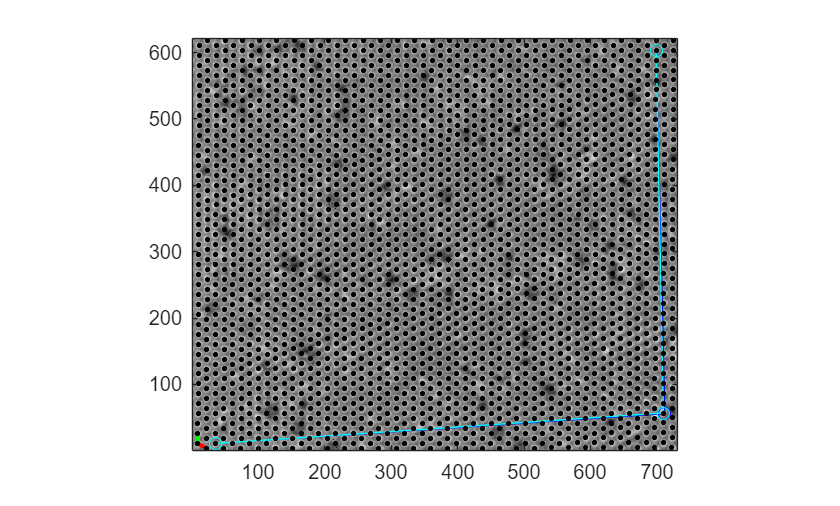

go =   Image with properties:

           CData: [621×731 double]
    CDataMapping: 'scaled'

  Show all properties


visualize(Z,a);

define 3 points

indLatt = [2 54 53; 1 30 66]

indLatt =      2    54    53
     1    30    66


fcs_xy = a.oB2pC(indLatt)

fcs_xy =    35.0364  711.9818  698.9636
   11.0000   56.0000  603.5000


shif_xy = [0 -2 0;0 1 0]

shif_xy =      0    -2     0
     0     1     0


fcs_xy_shifted = fcs_xy + shif_xy

fcs_xy_shifted =    35.0364  709.9818  698.9636
   11.0000   57.0000  603.5000


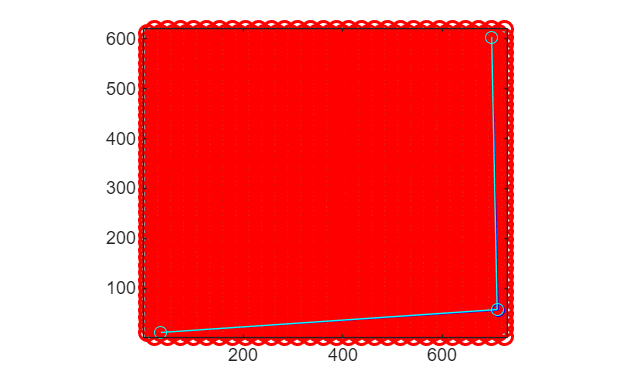

hold on
plot(fcs_xy(1,:),fcs_xy(2,:),'bo-')
plot(fcs_xy_shifted(1,:),fcs_xy_shifted(2,:),'co-')
hold off

b = a.latticeFineTune(indLatt,shif_xy)

b = ans =

    'reCalculated'

  grid2d with properties:

     offset_stdpts: [9.0831 10.9584]
         a1_stdpts: [12.9498 -7.4658]
         a2_stdpts: [0.0537 14.9732]
         sz_stdpts: [731 621]
            clr_a1: [1 0 0]
            clr_a2: [0 1 0]
    clr_faceWindow: [0 1 1]
    clr_edgeWindow: [0 0 1]
            augMat: [3×3 table]
           baryBss: [2×3 table]
            inLatt: [2324×2 table]
            inGrid: [126×4 table]


hold on
b.pLatticeWin

ans = 'reCalculated'

xy =     9.0831   10.9584
    9.1368   25.9316
    9.1904   40.9048
    9.2441   55.8780
    9.2977   70.8511
    9.3514   85.8243
    9.4050  100.7975
    9.4587  115.7706
    9.5124  130.7438
    9.5660  145.7170
    9.6197  160.6902
    9.6733  175.6633
    9.7270  190.6365
    9.7806  205.6097
    9.8343  220.5829


ans = 'reCalculated'

ans = 'reCalculated'

ans =   Line with properties:

              Color: [0 0 0]
          LineStyle: 'none'
          LineWidth: 1.5000
             Marker: '.'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [9.0831 9.1368 9.1904 9.2441 9.2977 9.3514 9.4050 9.4587 9.5124 9.5660 9.6197 9.6733 9.7270 9.7806 9.8343 9.8880 9.9416 9.9953 10.0489 10.1026 10.1562 10.2099 10.2635 10.3172 10.3709 10.4245 10.4782 10.5318 … ] (1×2324 double)
              YData: [10.9584 25.9316 40.9048 55.8780 70.8511 85.8243 100.7975 115.7706 130.7438 145.7170 160.6902 175.6633 190.6365 205.6097 220.5829 235.5560 250.5292 265.5024 280.4755 295.4487 310.4219 325.3951 340.3682 355.3414 … ] (1×2324 double)

  Show all properties

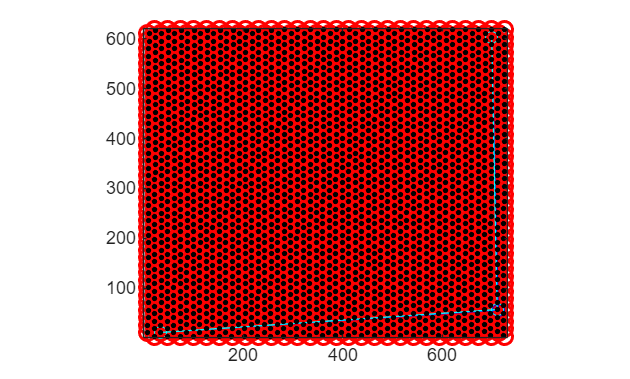

hold off

f = gcf

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


redot = f.Children.Children(4)

redot =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 1.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 … ] (1×2324 double)
              YData: [11 26 41 56 71 86 101 116 131 146 161 176 191 206 221 236 251 266 281 296 311 326 341 356 371 386 401 416 431 446 461 476 491 506 521 536 551 566 581 596 611 3.5000 18.5000 33.5000 48.5000 63.5000 78.5000 93.5000 … ] (1×2324 double)

  Show 

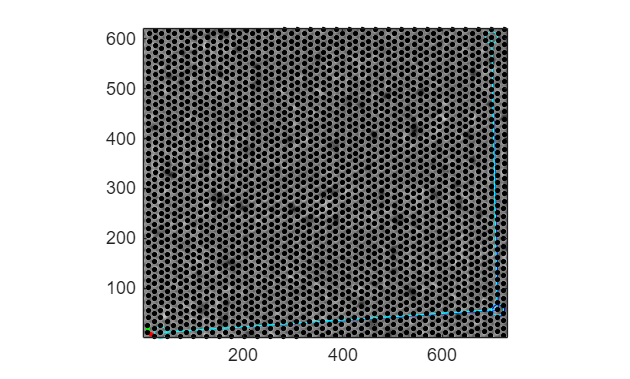

redot =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 1.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 … ] (1×2324 double)
              YData: [11 26 41 56 71 86 101 116 131 146 161 176 191 206 221 236 251 266 281 296 311 326 341 356 371 386 401 416 431 446 461 476 491 506 521 536 551 566 581 596 611 3.5000 18.5000 33.5000 48.5000 63.5000 78.5000 93.5000 … ] (1×2324 double)

  Show 

redot.Visible = 'off'

function visualize(Z,a)
gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";

views(Z)

colormap gray
hold on
a.pBases
hold off
hold on
p = a.pLatticeWin
p.Color = [1 0 0];
p.Marker ="o"
hold off
% hold on
% a.pGridlineWin
% hold off
f = gcf()
go = findobj(f,'type','image')
go.HitTest = 'off'
end

function a = consturctGrid(I_P__C,line_info,Z)
a = grid2d();
a.a1_stdpts = I_P__C(:,1);
a.a2_stdpts = I_P__C(:,2);
a.offset_stdpts = line_info(:,1,:);
a.sz_stdpts = size(Z);
a.inLatt
a.inGrid
end

function I_P__C = constructBases(line_info)
%P: pixel Coord
%B: line profile Coord
%C: lattice Coord
%Target: I_P__C
b1_x = (line_info(:,2,1) - line_info(:,1,1)) / (line_info(:,3,1)-1);
b2_y = (line_info(:,2,2) - line_info(:,1,2)) / (line_info(:,3,2)-1);
I_P__B = [b1_x 0;0 b2_y];
I_B__C = [1 0;-1/2 1];
I_P__C = I_P__B*I_B__C;
end